%*********************************************************************************************%
% Assume the size of Room is 10m * 10m *4m and the only LED in the ceil of the center of room %
% We define the lower left corner as the origin point (0, 0, 0) and the                       %
% other three point is (0, 10, 0), (10, 0, 0), (10, 10, 0), the coordinate                    %
% of the LED in this Coordinate system is (5, 5, 4). The Normal Vector of                     %
% LED is constant (0, 0, -1) in our consider(in most case this is                             %
% reasonable because the fixed LED installation Method), and the Normal                       %
% Vector of PD is random because of the rotation and moving, But we think                     %
% we can get this information throught the internal sensor of the phone                       %
%*********************************************************************************************%
%Summary                                                                                      %
%Size of the room 10m * 10m *4m                                                               %
%Coordinate of LED (5, 5, 4)                                                                  %
%Normal Vector of LED (0, 0, -1)                                                              %
%*********************************************************************************************%
clear 
clc
%*******************************Basical Parameter Setting*************************************%
global P_led X_led X_pd Self_Power_Angle_led Self_Power_Angle_pd AR P_Ti
Longofroom = 10;
Widthofroom = 10;
Heighofroom = 4;
m=1;
M=1;
AR    = 1;                  %Recieve are of pd (unit:cm^2)
P_Ti  = 1;                  %Transmit power of led (unit:unknown)
X_led = [0  0 -1];          %Direction Vector of LED(Assume We have known)                                     
P_led = [5  5  4];          %Position of LED

Self_Power_Angle_led = 60;  %Self Power angle of led (for Lambertian Order equal to 1, we set this as 60)
Self_Power_Angle_pd  = 60;  %Self Power angle of pd

%****************************Setting the Locating sample point********************************%
X_step = 2;
Y_step = 2;
Z_position = 0.5;
% P_pd = zeros(length(0:X_step:Longofroom)*length(0:Y_step:Widthofroom),3);
% for i = 0:X_step:Longofroom
%     for j = 0:Y_step:Widthofroom
%         P_pd(((i+X_step)/X_step-1)*length(0:X_step:Longofroom)+(j+Y_step)/Y_step,:) = [i  j  0.5];
%     end
% end
P_pd = [2.5 2.5 1;
        2.5 5.0 1;
        2.5 7.5 1;
        5.0 2.5 1;
        5.0 5.0 1;
        5.0 7.5 1;
        7.5 2.5 1;
        7.5 5.0 1;
        7.5 7.5 1]

P_pd =     2.5000    2.5000    1.0000
    2.5000    5.0000    1.0000
    2.5000    7.5000    1.0000
    5.0000    2.5000    1.0000
    5.0000    5.0000    1.0000
    5.0000    7.5000    1.0000
    7.5000    2.5000    1.0000
    7.5000    5.0000    1.0000
    7.5000    7.5000    1.0000


X_pd =zeros(3,3,size(P_pd,1));
%******************Using Lambertian Emiting Formula Calculate Recieve Power********************%
% Recieve_Power = Tool_Calculate_TheoreticalPower( P_pd )
Recieve_Power = zeros(size(P_pd,1),3);
for i=1:size(P_pd,1)
    X_pd(:,:,i) = Facing_Vector(P_pd(i,:) , P_led);
    Recieve_Power(i,:) = Theory_Power(P_pd(i,:), P_led, X_pd(:,:,i), X_led, m, M, AR);
end
%********Using Recieve Power and Direction Vector of Phone to solve Position estimation********%
Estimation_Position = Tool_Position_Estimation( Recieve_Power )

Estimation_Position =     2.4969    2.4969    0.9923
    2.4966    5.0000    1.0026
    2.4969    7.5031    0.9923
    5.0000    2.4966    1.0026
    5.0000    5.0000    1.0000
    5.0000    7.5034    1.0026
    7.5031    2.4969    0.9923
    7.5034    5.0000    1.0026
    7.5031    7.5031    0.9923


P_pd

P_pd =     2.5000    2.5000    1.0000
    2.5000    5.0000    1.0000
    2.5000    7.5000    1.0000
    5.0000    2.5000    1.0000
    5.0000    5.0000    1.0000
    5.0000    7.5000    1.0000
    7.5000    2.5000    1.0000
    7.5000    5.0000    1.0000
    7.5000    7.5000    1.0000


plot3(P_pd(:,1), P_pd(:,2), P_pd(:,3),'.','Color','b','MarkerSize',16);
hold on
plot3(Estimation_Position(:,1), Estimation_Position(:,2), Estimation_Position(:,3),'.','Color','r','MarkerSize',16);
grid on
legend('Real Position','Simulation Result')
Err = Estimation_Position - P_pd;
Err = Err.^2;
Err = sum(Err,2);
Err = sqrt(Err);
Err_aver = mean(Err)

Err_aver = 0.0058

Err_without_bigerr_point = mean(Err(1:length(Err)-1))

Err_without_bigerr_point = 0.0055

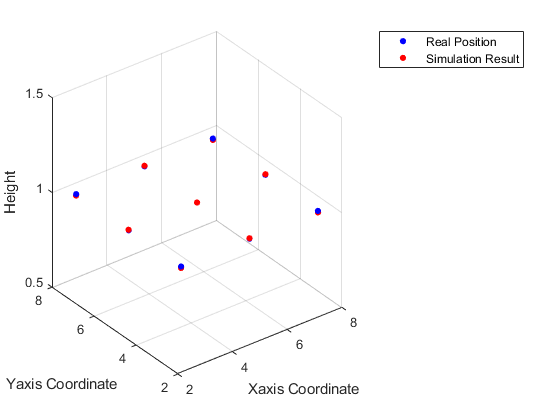

xlabel('Xaxis Coordinate')
ylabel('Yaxis Coordinate')
zlabel('Height')
zlim([0.5 1.5])